### ABV Docking System Achievability Analysis

clear; clc; close all;

% ABV Parameters (abv_gnc)
m_abv = 12.7; % kg, dry ABV mass
n_thrusters_lin = 2; % thrusters firing for translation (ASSUMPTION)
n_thrusters_rot = 2; % thrusters firing for rotation (ASSUMPTION)
r_arm = 0.1235; % m, thruster moment arm (config.yaml)
F_thruster = 0.1;   % N per thruster: 0.1 = conservative placeholder, 0.82 = orifice model @ 60 psig


% ABV Geometry
ft2m = 0.3048; % ft to meters
abv_length = 1.125 * ft2m;  % m
abv_width = 1.125 * ft2m;  % m
% abv_height = 1.1667 * ft2m;  % m (for reference only)

% Air Bearing Table Geometry
table_length = 3.6; % m
table_width = 1.8; % m

% Requirements
v_min = 0.05; % m/s, SYS.10 lower bound
v_max = 0.10; % m/s, SYS.10 upper bound
radial_offset = 0.10; % m, SYS.07 max radial offset
angular_offset = deg2rad(4); % rad, SYS.08 max angular offset (4 deg)
% Note: roll not used here

% Mass range
m_payload = linspace(0, 10, 21); % kg, 0-10 kg in 0.5 kg increments

% Computed parameters
m_total = m_abv + m_payload; % kg, wet ABV mass
F_lin_net = n_thrusters_lin * F_thruster; % N
tau_net = n_thrusters_rot * F_thruster * r_arm; % N*m

a_lin = F_lin_net ./ m_total; % m/s^2, linear accel

% ABV MOI (yaw)
r_mech_mount = abv_length/2;                      
M_crit_tank = 1.695 * 9.81 * (26*0.0254);       
m_ground = M_crit_tank / (9.81 * r_mech_mount);   % kg, grounding limit at r_mech_mount
I_abv = (1/12)*m_abv*(abv_length^2 + abv_width^2) ...
        + (m_abv .* m_payload * r_mech_mount^2) ./ m_total;   % parallel axis
alpha_rot = tau_net ./ I_abv;


%% Time/distance to reach velocity
t_to_vmin = v_min ./ a_lin; % s
t_to_vmax = v_max ./ a_lin; % s

s_to_vmin = (v_min^2) ./ (2 * a_lin); % m, distance to v_min
s_to_vmax = (v_max^2) ./ (2 * a_lin); % m, distance to v_max

target_depth = 0.30;   % m, passive target footprint (VERIFY)
L_avail  = table_length - abv_length - target_depth;   % m, travel for ABV center
s_brake  = v_max^2 ./ (2 * a_lin);                     % m, stopping distance
s_remaining = L_avail - s_to_vmax - s_brake;           % m, cruise left with abort margin

%% Lateral (radial offset) table clearance check
lateral_clearance = (table_width / 2) - radial_offset - (abv_width / 2);

% Time to set up angular offset
t_establish_yaw = 2 * sqrt(angular_offset ./ alpha_rot);   % rest-to-rest

% Summary
fprintf('\n ACHIEVABILITY ANALYSIS SUMMARY \n');


 ACHIEVABILITY ANALYSIS SUMMARY 


fprintf('%8s %10s %10s %10s %10s %10s %12s\n', ...
    'm_pay', 'a_lin', 't->vmax', 's->vmax', 's_remain', 'alpha', 't_ang');

   m_pay      a_lin    t->vmax    s->vmax   s_remain      alpha        t_ang


fprintf('%8s %10s %10s %10s %10s %10s %12s\n', ...
    '(kg)', '(m/s^2)', '(s)', '(m)', '(m)', '(rad/s^2)', '(s)');

    (kg)    (m/s^2)        (s)        (m)        (m)  (rad/s^2)          (s)


for i = 1:length(m_payload)
    fprintf('%8.1f %10.5f %10.2f %10.3f %10.3f %10.5f %12.2f\n', ...
        m_payload(i), a_lin(i), t_to_vmax(i), s_to_vmax(i), ...
        s_remaining(i), alpha_rot(i), t_establish_yaw(i));
end

     0.0    0.01575       6.35      0.318      2.322    0.09925         1.68
     0.5    0.01515       6.60      0.330      2.297    0.09391         1.72
     1.0    0.01460       6.85      0.343      2.272    0.08945         1.77
     1.5    0.01408       7.10      0.355      2.247    0.08567         1.81
     2.0    0.01361       7.35      0.368      2.222    0.08242         1.84
     2.5    0.01316       7.60      0.380      2.197    0.07961         1.87
     3.0    0.01274       7.85      0.393      2.172    0.07714         1.90
     3.5    0.01235       8.10      0.405      2.147    0.07495         1.93
     4.0    0.01198       8.35      0.418      2.122    0.07301         1.96
     4.5    0.01163       8.60      0.430      2.097    0.07127         1.98
     5.0    0.01130       8.85      0.443      2.072    0.06971         2.00
     5.5    0.01099       9.10      0.455      2.047    0.06829         2.02
     6.0    0.01070       9.35      0.468      2.022    0.06700         2.04

fprintf('========================================================================\n\n');


% Error
infeasible_idx = find(s_remaining < 0, 1, 'first');
if ~isempty(infeasible_idx)
        fprintf(['WARNING: At payload mass >= %.1f kg, the ABV cannot reach v_max\n' ...
             'and stop again within the available approach length (%.2f m).\n\n'], ...
             m_payload(infeasible_idx), L_avail);
else
    fprintf('No infeasible mass points found in this sweep (0-10 kg) -- workspace\n');
    fprintf('margin remains positive across the full range. See plots for how\n');
    fprintf('tight that margin gets as mass increases.\n\n');
end

No infeasible mass points found in this sweep (0-10 kg) -- workspace


margin remains positive across the full range. See plots for how


tight that margin gets as mass increases.



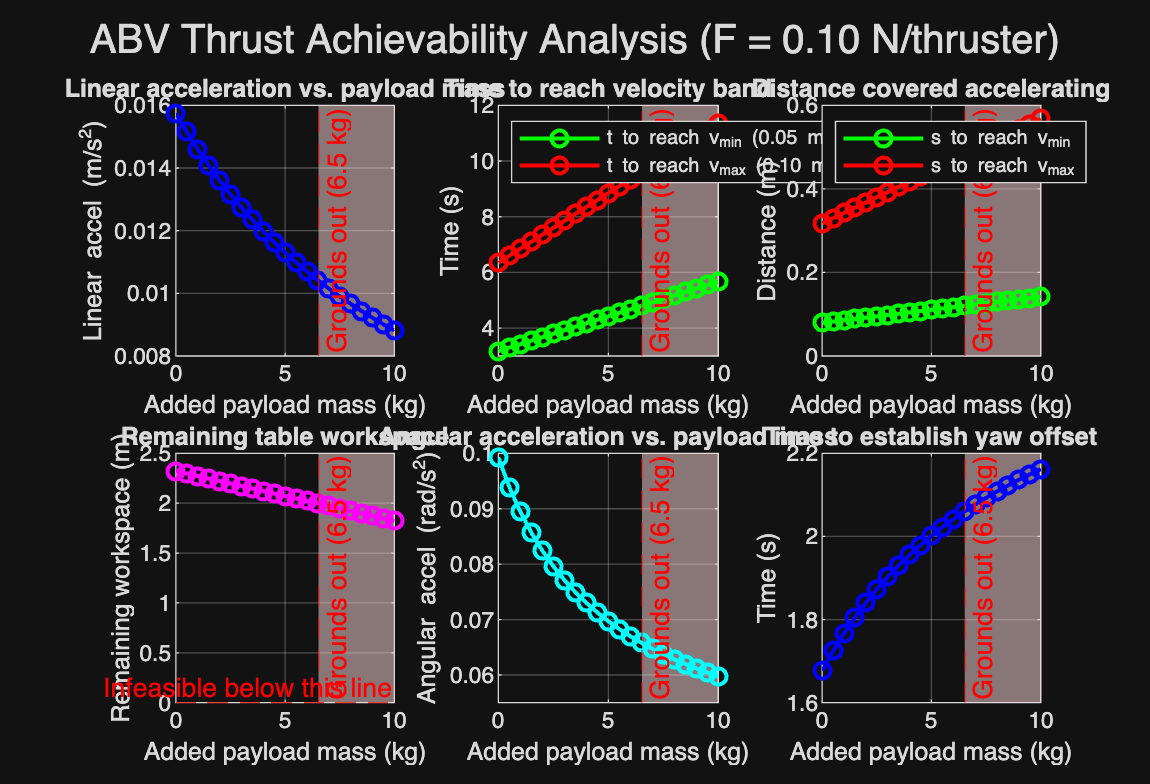

if lateral_clearance < 0
    fprintf('WARNING: offset position does not fit within table width.\n');
end

%% Graphs

figure('Name', 'ABV Achievability Analysis', 'Position', [100 100 1100 750]);

subplot(2,3,1);
plot(m_payload, a_lin, 'b-o', 'LineWidth', 1.5);
xlabel('Added payload mass (kg)'); ylabel('Linear accel (m/s^2)');
title('Linear acceleration vs. payload mass'); grid on;
mark_ground_limit(m_ground);

subplot(2,3,2);
plot(m_payload, t_to_vmin, 'g-o', m_payload, t_to_vmax, 'r-o', 'LineWidth', 1.5);
xlabel('Added payload mass (kg)'); ylabel('Time (s)');
legend('t to reach v_{min} (0.05 m/s)', 't to reach v_{max} (0.10 m/s)', 'Location', 'northwest');
title('Time to reach velocity band'); grid on;
mark_ground_limit(m_ground);

subplot(2,3,3);
plot(m_payload, s_to_vmin, 'g-o', m_payload, s_to_vmax, 'r-o', 'LineWidth', 1.5);
xlabel('Added payload mass (kg)'); ylabel('Distance (m)');
legend('s to reach v_{min}', 's to reach v_{max}', 'Location', 'northwest');
title('Distance covered accelerating'); grid on;
mark_ground_limit(m_ground);

subplot(2,3,4);
plot(m_payload, s_remaining, 'm-o', 'LineWidth', 1.5);
yline(0, 'r--', 'Infeasible below this line');
xlabel('Added payload mass (kg)'); ylabel('Remaining workspace (m)');
title('Remaining table workspace'); grid on;
mark_ground_limit(m_ground);

subplot(2,3,5);
plot(m_payload, alpha_rot, 'c-o', 'LineWidth', 1.5);
xlabel('Added payload mass (kg)'); ylabel('Angular accel (rad/s^2)');
title('Angular acceleration vs. payload mass'); grid on;
mark_ground_limit(m_ground);

subplot(2,3,6);
plot(m_payload, t_establish_yaw, 'b-o', 'LineWidth', 1.5);
xlabel('Added payload mass (kg)'); ylabel('Time (s)');
title('Time to establish yaw offset'); grid on;
mark_ground_limit(m_ground);

sgtitle(sprintf('ABV Thrust Achievability Analysis (F = %.2f N/thruster)', F_thruster));


function mark_ground_limit(m_lim)
% Shade payload masses past the grounding limit on the current axes.
xl = xlim; yl = ylim;
if m_lim < xl(2)
    hold on;
    h = patch([m_lim xl(2) xl(2) m_lim], [yl(1) yl(1) yl(2) yl(2)], [1 0.85 0.85], ...
        'EdgeColor', 'none', 'FaceAlpha', 0.5, 'HandleVisibility', 'off');
    uistack(h, 'bottom');
    xline(m_lim, 'r--', sprintf('Grounds out (%.1f kg)', m_lim), ...
        'HandleVisibility', 'off', 'LabelVerticalAlignment', 'bottom');
    xlim(xl); ylim(yl);
end
end
